% signal to Noise Ratio values from 0.5 to 10
start_snr = 2;
end_snr = 8;
step_size =2;
snr_values = start_snr:step_size:end_snr;


% names for RF model: PA6 to PA101

start_value = 1;
end_value = 4;

% Generate the numeric sequence using the colon operator
numeric_sequence = start_value:end_value;

% Convert the numeric sequence to a cell array of strings
string_sequence = strcat('PA4_new_', string(numeric_sequence));


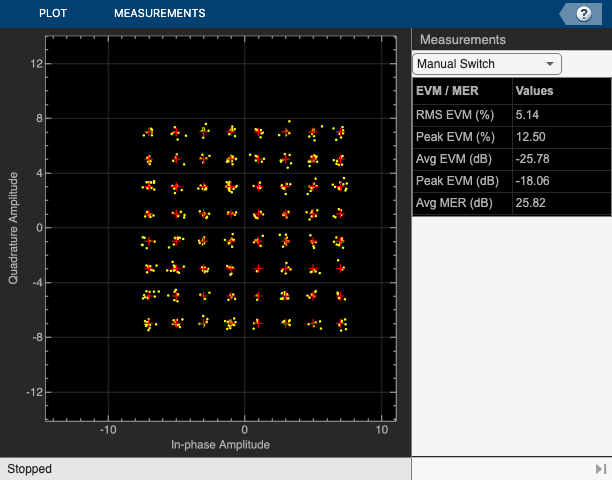

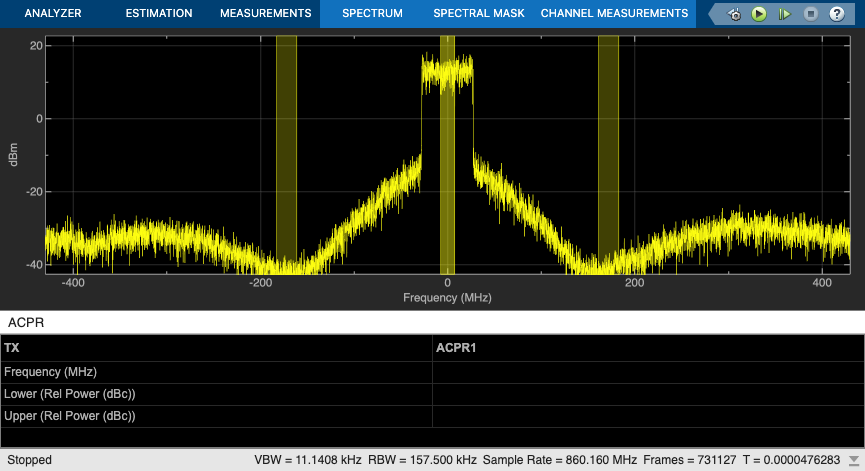

numElements = numel(snr_values);
data = {snr_values, string_sequence};
bw= 15000000;
degLen=5;
memLen=5;

cpLength=72;dataFileName="helperPACharSavedData15MHz";
fftLength=1024;N=283;
nGuardBandCarrier=566;NSubcarriers=456;
ofdmSymLen=1096;sampleRate=215040000;
windowLength=6;
mixer_noise=0;
model = 'simrfV2_powamp_dpd_comms';

for idx = 1:numElements
    amp_noise = data{1}(idx); % Access the element from numeric_sequence
    model_name = data{2}{idx};
    sim(model)
    file_timeseries = ['time_new/', model_name, '.csv'];
    file_phasor= ['phasor_new/', model_name, '.csv'];
    save_complex_data_to_csv(file_timeseries, Time_series.Data);
    save_complex_data_to_csv(file_phasor, phasor.Data);
    
end





%open_system(model)
%sim(model)
%file_timeseries = ['timeseries/PA', '5', '.csv']
%file_phasor= ['phasor/PA', '5', '.csv']
%save_complex_data_to_csv(file_timeseries, Time_series.Data);
%save_complex_data_to_csv(file_phasor, phasor.Data);



function save_complex_data_to_csv(filename, data)
    % Separate the real and imaginary parts of the complex data
    real_part = real(data);
    imag_part = imag(data);

    % Create a table with columns for real and imaginary parts
    table_data = table(real_part, imag_part, 'VariableNames', {'real', 'imag'});

    % Save the table to a CSV file
    writetable(table_data, filename);
end

